%%initialize environment
defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 8 - In vivo drug infusion');

binstep = 5;
bins = [0:binstep:125];
filelist = loadFileList('.\Data\MRS2500 IP\*\*ICDetailAnalysis*');
lcounts = []; rcounts = []; WTallcounts = [];
for i = 1:size(filelist,1)
    load(filelist{i})

    [peakStat, eventStats] = spatialPeakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
    eventStats = eventStats([eventStats.tloc] >= 0 & [eventStats.tloc] < 3000);
    lcounts(i,:) = histcounts([eventStats(strcmp({eventStats.eventClassification},'Left')).xloc eventStats.lxloc],bins);
    rcounts(i,:) = histcounts([eventStats(strcmp({eventStats.eventClassification},'Right')).xloc eventStats.rxloc],bins);
    WTallcounts = [WTallcounts; [eventStats(strcmp({eventStats.eventClassification},'Left')).xloc eventStats.lxloc]'; ...
                    125-[eventStats(strcmp({eventStats.eventClassification},'Right')).xloc eventStats.rxloc]'];
end
% figure;
% histogram('BinEdges',bins,'BinCounts',sum(lcounts,1))
% hold on;
% histogram('BinEdges',bins,'BinCounts',fliplr(sum(rcounts,1)));
WT_counts = lcounts + fliplr(rcounts);

filelist = loadFileList('.\Data\MRS2500 IP\*\*ICDetailAnalysis*');
lcounts = []; rcounts = []; MRSallcounts = [];
for i = 1:size(filelist,1)
    load(filelist{i})

    [peakStat, eventStats] = spatialPeakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);
    eventStats = eventStats([eventStats.tloc] >= 6000 & [eventStats.tloc] < 9000);
    lcounts(i,:) = histcounts([eventStats(strcmp({eventStats.eventClassification},'Left')).xloc eventStats.lxloc],bins);
    rcounts(i,:) = histcounts([eventStats(strcmp({eventStats.eventClassification},'Right')).xloc eventStats.rxloc],bins);
     MRSallcounts = [MRSallcounts; [eventStats(strcmp({eventStats.eventClassification},'Left')).xloc eventStats.lxloc]'; ...
                    125-[eventStats(strcmp({eventStats.eventClassification},'Right')).xloc eventStats.rxloc]'];

end
% figure;
% histogram('BinEdges',bins,'BinCounts',sum(lcounts,1))
% hold on;
% histogram('BinEdges',bins,'BinCounts',fliplr(sum(rcounts,1)));
MRS_counts = lcounts + fliplr(rcounts);

figure; histogram('BinEdges',bins,'BinCounts',mean(WT_counts,1),'FaceColor','k','EdgeColor','none'); hold on;
errorbar(bins(1:end-1)+binstep/2,mean(WT_counts,1),sterr(WT_counts,1),'Color','k','CapSize',0,'LineStyle','none','LineWidth',1)
histogram('BinEdges',bins,'BinCounts',mean(MRS_counts,1),'FaceColor','r','EdgeColor','none'); hold on;
errorbar(bins(1:end-1)+binstep/2,mean(MRS_counts,1),sterr(MRS_counts,1),'Color','r','CapSize',0,'LineStyle','none','LineWidth',1)
box off;
axh = gca;
axh.TickDir = 'out';
xlim([0 125]);
xticks([0 125/2 125])
xticklabels({'0','400','800'})
[h,p] = ttest2(WT_counts(:,4),MRS_counts(:,4))

h = 1

p = 0.0278

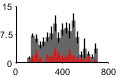

ylim([0 15])
yticks([0:7.5:15]);
figQuality(gcf,gca,[1.25 0.8])
print('.\EPS Panels\Distribution.pdf','-dpdf');

%divide IC into lateral and medial areas and compare frequencies
WT_counts_lat = sum(WT_counts(:,1:10),2)/5;
WT_counts_medial = sum(WT_counts(:,11:20),2)/5;
MRS_counts_lat = sum(MRS_counts(:,1:10),2)/5;
MRS_counts_medial = sum(MRS_counts(:,11:20),2)/5;
WTsize = size(WT_counts_lat,1);
MRSsize = size(MRS_counts_lat,1);


figure;
scatter(ones(1,WTsize)*.75,WT_counts_medial,8,[0.7 0.7 0.7],'filled'); hold on;
scatter(ones(1,MRSsize)*1.25,MRS_counts_medial,8,[0.7 0.7 0.7],'filled');
scatter(ones(1,WTsize)*.75+2,WT_counts_lat,8,[0.7 0.7 0.7],'filled');
scatter(ones(1,MRSsize)*1.25+2,MRS_counts_lat,8,[0.7 0.7 0.7],'filled');
errorbar([0.75 2.75],[mean(WT_counts_medial,1) mean(WT_counts_lat)],[sterr(WT_counts_medial,1) sterr(WT_counts_lat,1)],...
    'Color','k','CapSize',0,'LineStyle','none','LineWidth',1,'Marker','.','MarkerSize',12)
errorbar([1.25 3.25],[mean(MRS_counts_medial,1) mean(MRS_counts_lat)],[sterr(MRS_counts_medial,1) sterr(MRS_counts_lat,1)],...
    'Color','r','CapSize',0,'LineStyle','none','LineWidth',1,'Marker','.','MarkerSize',12)
ylim([0 20]);
xlim([0 4]);
xticks([1 3]);
xticklabels({'Medial','Lateral'});

[h,p] = ttest2(WT_counts_medial,MRS_counts_medial)

h = 1

p = 1.8313e-04

[h,p] = ttest2(WT_counts_lat,MRS_counts_lat)

h = 1

p = 1.5368e-04

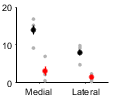

figQuality(gcf,gca,[1.25 1])
print('.\EPS Panels\Frequency.pdf','-dpdf');

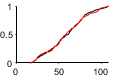

figure;
[f1,x1] = ecdf(WTallcounts);
[f2,x2] = ecdf(MRSallcounts);
plot(x1,f1,'Color','k'); hold on;
plot(x2,f2,'Color','r');
figQuality(gcf,gca,[1.25 .8]);
print('.\EPS Panels\cdf.pdf','-dpdf');